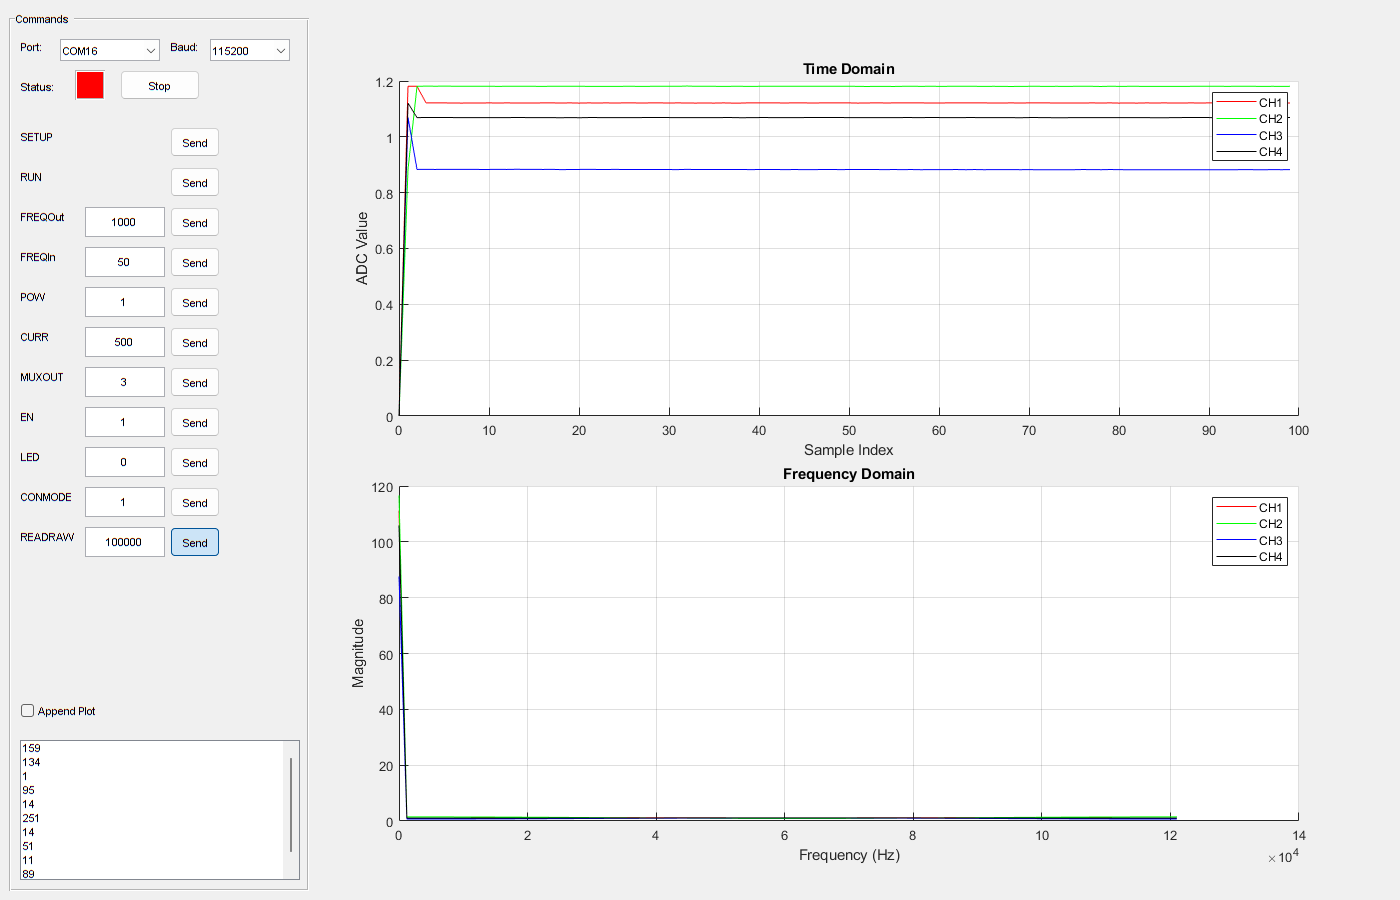

load("testy_03_03_25_biuro.mat");

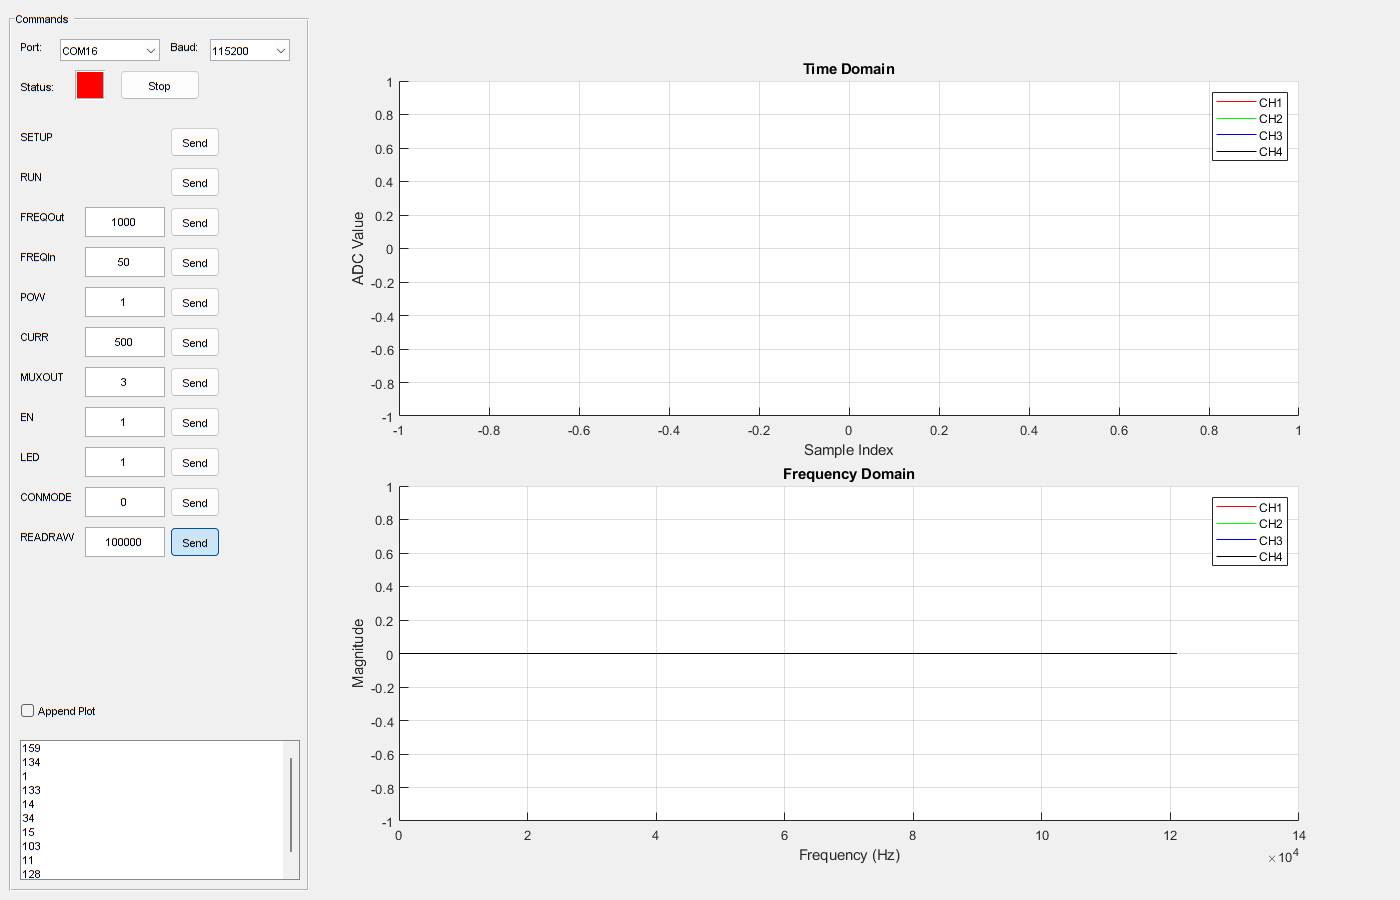

load("testy_04_03_25_biuro.mat");

load("testy_10_03_25_biuro_ref.mat", 'ch1', 'ch2', 'ch3', 'ch4', 'sampleIndex');

load("testy_10_03_25_biuro_bpm55.mat", 'ch1', 'ch2', 'ch3', 'ch4', 'sampleIndex');

load("lab_12_03_test1.mat")

function I = radar_echo(ch1, ch2, ch3, ch4)
    P4 = (vpa(ch3,5) - 14970.8) / 369.597;
    P3 = (vpa(ch2,5) - 14970.8) / 369.597;
    P2 = (vpa(ch4,5) - 14970.8) / 369.597;
    Pref = (vpa(ch1,5) - 14970.8) / 369.597;
    P4norm = P4-Pref;
    P3norm = P3-Pref;
    P2norm = P2-Pref;
    P4norm = 10.^(P4norm/10);
    P3norm = 10.^(P3norm/10);
    P2norm = 10.^(P2norm/10);
    I = -P2norm+0.5*P3norm+0.5*P4norm+1i*sqrt(3)/2*(-P3norm+P4norm);
end

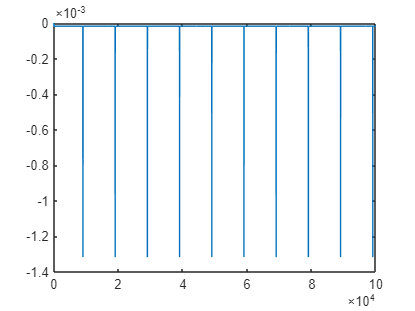

plot(sampleIndex, I);

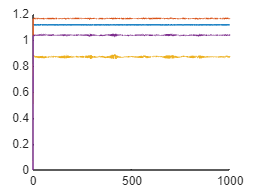

figure(1); clf; hold on;
plot(sampleIndex, ch1);
plot(sampleIndex, ch2);
plot(sampleIndex, ch3);
plot(sampleIndex, ch4);

ch1_filtered = ch1;
ch2_filtered = ch2;
ch3_filtered = ch3;
ch4_filtered = ch4;

for i = find(ch1 == max(ch1))
    disp(ch1_filtered(i));
    disp(ch1_filtered(i-1));
    ch1_filtered(i) = ch1_filtered(i-1);
    ch2_filtered(i) = ch2_filtered(i-1);
    ch3_filtered(i) = ch3_filtered(i-1);
    ch4_filtered(i) = ch4_filtered(i-1);
    disp(ch1_filtered(i));
    disp(ch1_filtered(i-1));
    disp(i);
end

    1.1179



    1.1169



    1.1169



    1.1169



   574



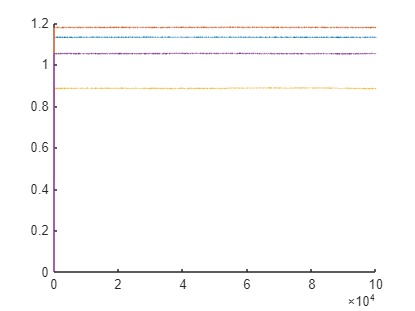

figure(1); clf; hold on;
plot(sampleIndex, ch1_filtered);
plot(sampleIndex, ch2_filtered);
plot(sampleIndex, ch3_filtered);
plot(sampleIndex, ch4_filtered);

%%% CALCULATING RADAR ECHO

%BPM55 VALUES
ch1_filtered_bpm55 = ch1;
ch2_filtered_bpm55 = ch2;
ch3_filtered_bpm55 = ch3;
ch4_filtered_bpm55 = ch4;
I_bpm55 = radar_echo(ch1_filtered_bpm55, ch2_filtered_bpm55, ch3_filtered_bpm55, ch4_filtered_bpm55)

%REF VALUES
ch1_filtered_ref = ch1_filtered;
ch2_filtered_ref = ch2_filtered;
ch3_filtered_ref = ch3_filtered;
ch4_filtered_ref = ch4_filtered;
I_ref = radar_echo(ch1_filtered_ref, ch2_filtered_ref, ch3_filtered_ref, ch4_filtered_ref)

I_ref = 1.0e-04 *

   0.0000 + 0.0000i  -0.1804 + 0.0275i  -0.1800 + 0.0275i  -0.1800 + 0.0275i  -0.1799 + 0.0277i  -0.1799 + 0.0277i  -0.1803 + 0.0277i  -0.1801 + 0.0274i  -0.1798 + 0.0275i  -0.1799 + 0.0281i  -0.1800 + 0.0275i  -0.1800 + 0.0275i  -0.1800 + 0.0275i  -0.1798 + 0.0279i  -0.1798 + 0.0279i  -0.1798 + 0.0275i  -0.1802 + 0.0275i  -0.1800 + 0.0275i  -0.1803 + 0.0277i  -0.1800 + 0.0275i  -0.1803 + 0.0274i  -0.1798 + 0.0279i  -0.1800 + 0.0272i  -0.1800 + 0.0279i  -0.1796 + 0.0275i  -0.1799 + 0.0277i  -0.1800 + 0.0279i  -0.1799 + 0.0277i  -0.1800 + 0.0275i  -0.1798 + 0.0275i  -0.1798 + 0.0275i  -0.1800 + 0.0275i  -0.1801 + 0.0277i  -0.1800 + 0.0275i  -0.1796 + 0.0272i  -0.1801 + 0.0277i  -0.1800 + 0.0275i  -0.1797 + 0.0277i  -0.1795 + 0.0277i  -0.1801 + 0.0274i  -0.1801 + 0.0277i  -0.1803 + 0.0281i  -0.1800 + 0.0275i  -0.1797 + 0.0277i  -0.1802 + 0.0275i  -0.1798 + 0.0275i  -0.1801 + 0.0281i  -0.1800 + 0.0275i  -0.1799 + 0.0277i  -0.1800 + 0.0275i


I_final = I_bpm55 - I_ref;

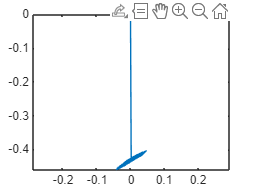

figure(5); clf; 
plot(real(I_bpm55), imag(I_bpm55));
axis Equal;

ch1_movedto0 = ch1_filtered(2:end) - ones(size(ch1_filtered(2:end)))*mean(ch1_filtered(2:end));
ch2_movedto0 = ch2_filtered(2:end) - ones(size(ch2_filtered(2:end)))*mean(ch2_filtered(2:end));
ch3_movedto0 = ch3_filtered(2:end) - ones(size(ch3_filtered(2:end)))*mean(ch3_filtered(2:end));
ch4_movedto0 = ch4_filtered(2:end) - ones(size(ch4_filtered(2:end)))*mean(ch4_filtered(2:end));
sampleIndex_moveto0 = sampleIndex(2:end);

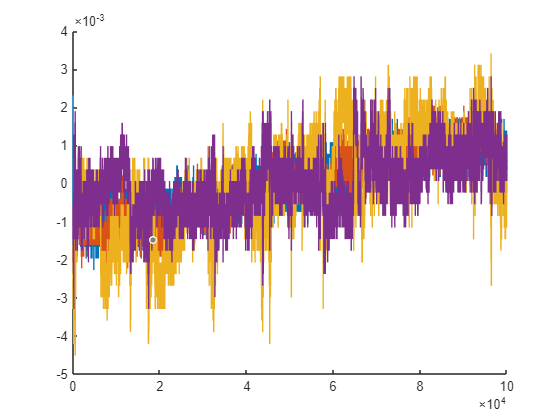

figure(2); clf; hold on;
plot(sampleIndex_moveto0, ch1_movedto0);
plot(sampleIndex_moveto0, ch2_movedto0);
plot(sampleIndex_moveto0, ch3_movedto0);
plot(sampleIndex_moveto0, ch4_movedto0);

fsampling = 1000;
fch1_clean = fft(ch1_movedto0);
%fch1_clean = [fch1_clean((length(fch1_clean)-1)/2:end), fch1_clean(1:(length(fch1_clean)-1)/2)];
fch2_clean = fft(ch2_movedto0);
%fch2_clean = [fch2_clean((length(fch2_clean)-1)/2:end), fch2_clean(1:(length(fch2_clean)-1)/2)];
fch3_clean = fft(ch3_movedto0);
%fch3_clean = [fch3_clean((length(fch3_clean)-1)/2:end), fch3_clean(1:(length(fch3_clean)-1)/2)];
fch4_clean = fft(ch4_movedto0);
%fch4_clean = [fch4_clean((length(fch4_clean)-1)/2:end), fch4_clean(1:(length(fch4_clean)-1)/2)];

%f = linspace(-fsampling/2, fsampling/2, length(fch1_clean));
f = linspace(0, fsampling, length(fch1_clean));

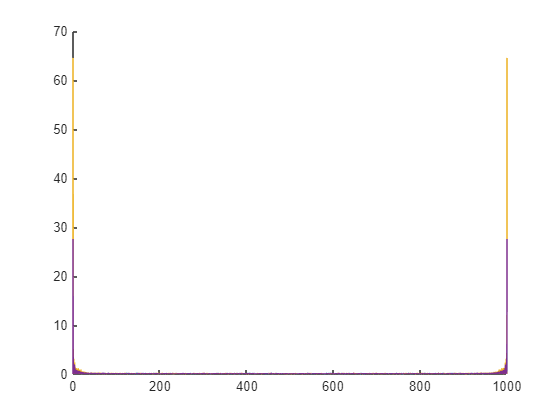

figure(3); clf; hold on;
plot(f, abs(fch1_clean));
plot(f, abs(fch2_clean));
plot(f, abs(fch3_clean));
plot(f, abs(fch4_clean));

fft_clean = abs(fch1_clean) + abs(fch2_clean) + abs(fch3_clean) + abs(fch4_clean);

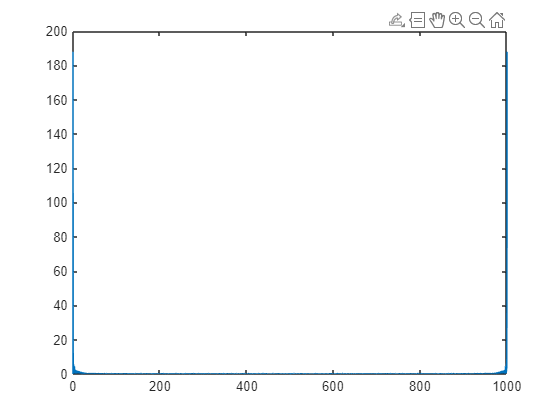

figure(4); clf; 
plot(f, fft_clean);